# Exercise 8

clear all; close all; clc;

## Question 1

Calibrate the Camera

stereo_params = stereoCalibrateCamera('calib_images', 'SquareSize', 15);

## Check the reprojection errors

err1 = vecnorm(stereo_params.CameraParameters1.ReprojectionErrors, 2, 2);
err2 = vecnorm(stereo_params.CameraParameters2.ReprojectionErrors, 2, 2);
errors = [err1, err2];
std(errors(:))

ans = 0.0901

mean(errors(:))

ans = 0.1560

## Question 2

Load all images and convert them into gray scale

% root is the folder
root = 'angel_rect/frames';
% for each camera, we take 21 images
imgNum = 18;
camera = 0;% camera: 0, 1
for imgIdx = 0:imgNum-1
    im = imread(root+string(camera)+'_'+string(imgIdx)+'.png');
    im = rgb2gray(im);
    if imgIdx<2
            eval('im'+string(camera)+'_'+string(imgIdx)+'=im;');
            prim1 = zeros([(imgNum-2)/2, size(im)]);
            sec1 = prim1;
    end
    if imgIdx>1 && imgIdx<10
        prim1(imgIdx-1,:,:) = im;
    end
    if imgIdx>9
        sec1(imgIdx-9,:,:) = im;
    end
    %figure;
    %imshow(im);
end
camera = 1;% camera: 0, 1
for imgIdx = 0:imgNum-1
    im = imread(root+string(camera)+'_'+string(imgIdx)+'.png');
    im = rgb2gray(im);
    if imgIdx<2
            eval('im'+string(camera)+'_'+string(imgIdx)+'=im;');
            prim2 = zeros([(imgNum-2)/2, size(im)]);
            sec2 = prim2;
    end
    if imgIdx>1 && imgIdx<10
        prim2(imgIdx-1,:,:) = im;
    end
    if imgIdx>9
        sec2(imgIdx-9,:,:) = im;
    end
    %figure;
    %imshow(im);
end

## Question 3

Create a mask

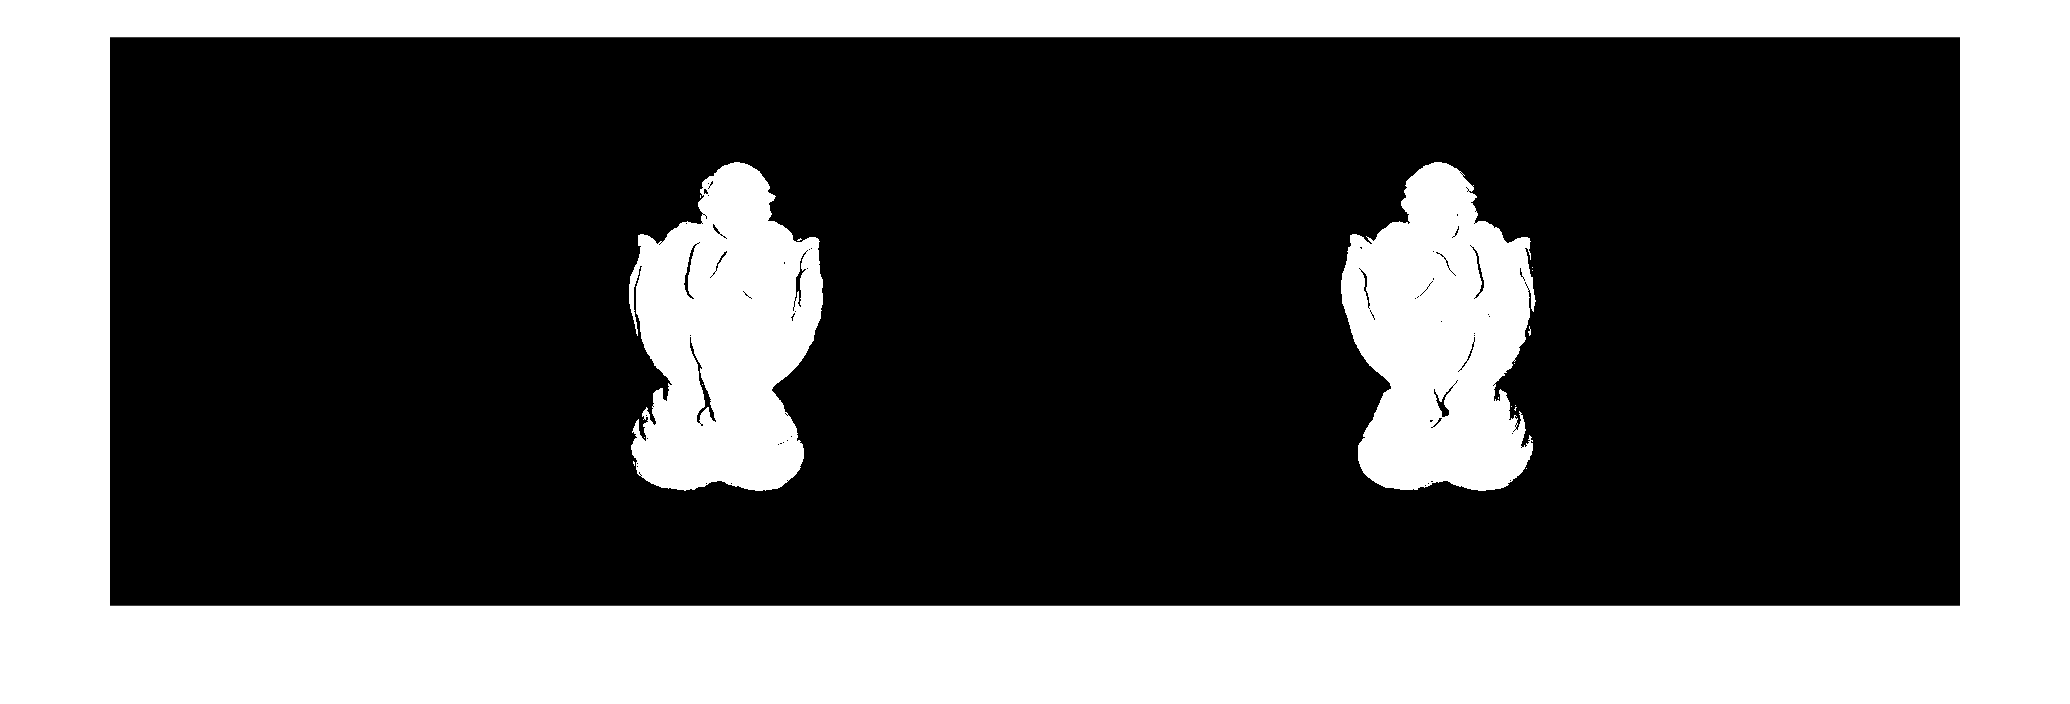

im = im0_0-im0_1;
%imshow(im)
mask1 = ones(size(im));
mask1(1, :) = 0;
mask1(end, :) = 0;
mask1(:, 1) = 0;
mask1(:, end) = 0;
%imshow(mask1);
mask1 = mask1&(im>0.1*255)&(im<0.9*255);
im = im1_0-im1_1;
%imshow(im)
mask2 = ones(size(im));
mask2(1, :) = 0;
mask2(end, :) = 0;
mask2(:, 1) = 0;
mask2(:, end) = 0;
%imshow(mask2);
mask2 = mask2&(im>0.1*255)&(im<0.9*255);
imshowpair(mask1, mask2, 'montage');

## Question 4

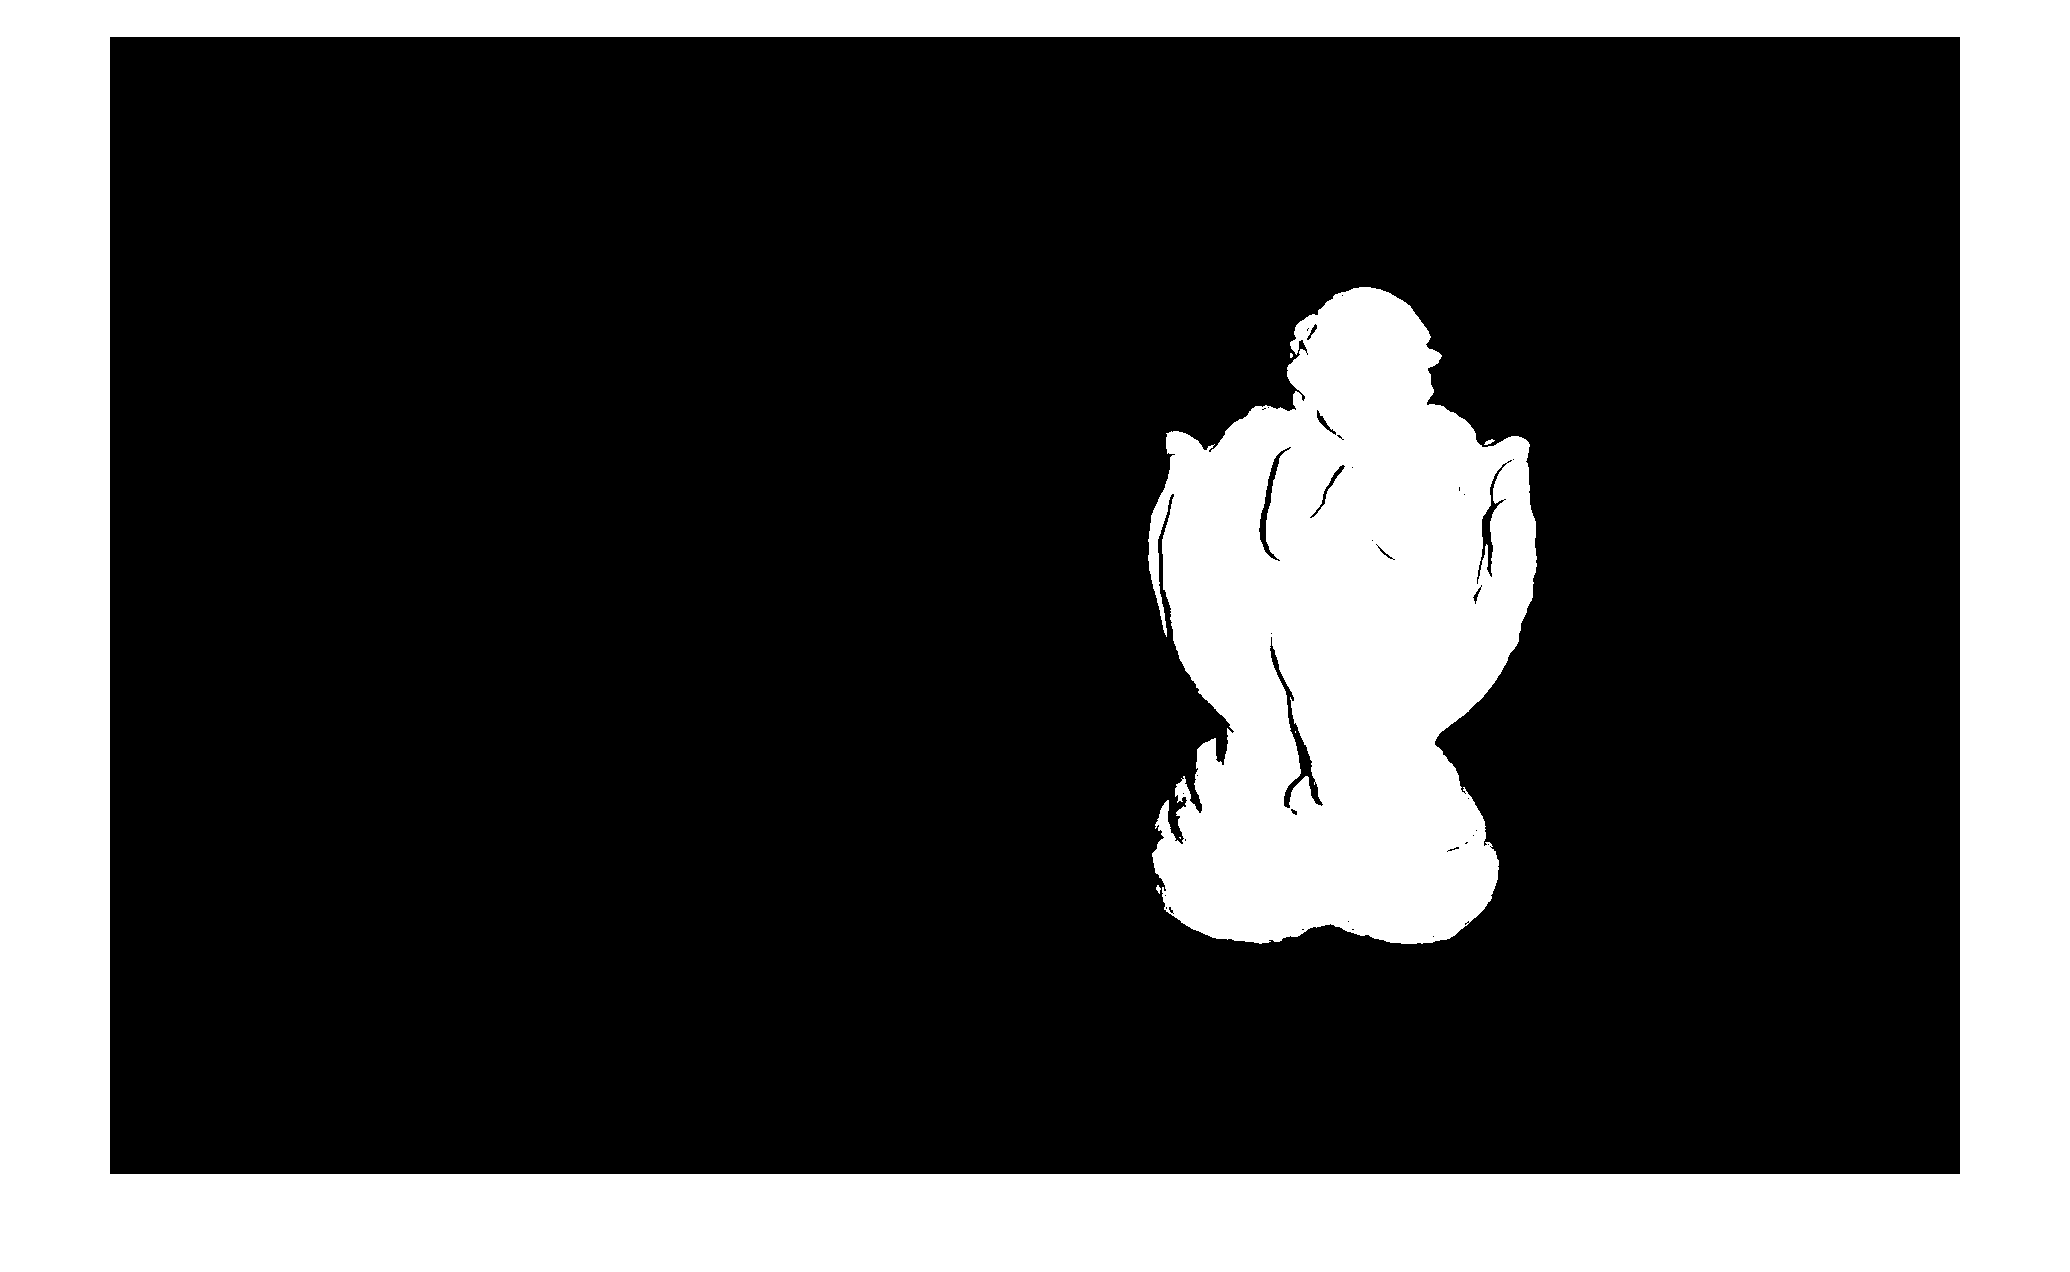

phase1 = decodePhase(prim1, sec1);
phase1 = phase1.*mask1;
figure;
imshow(phase1);

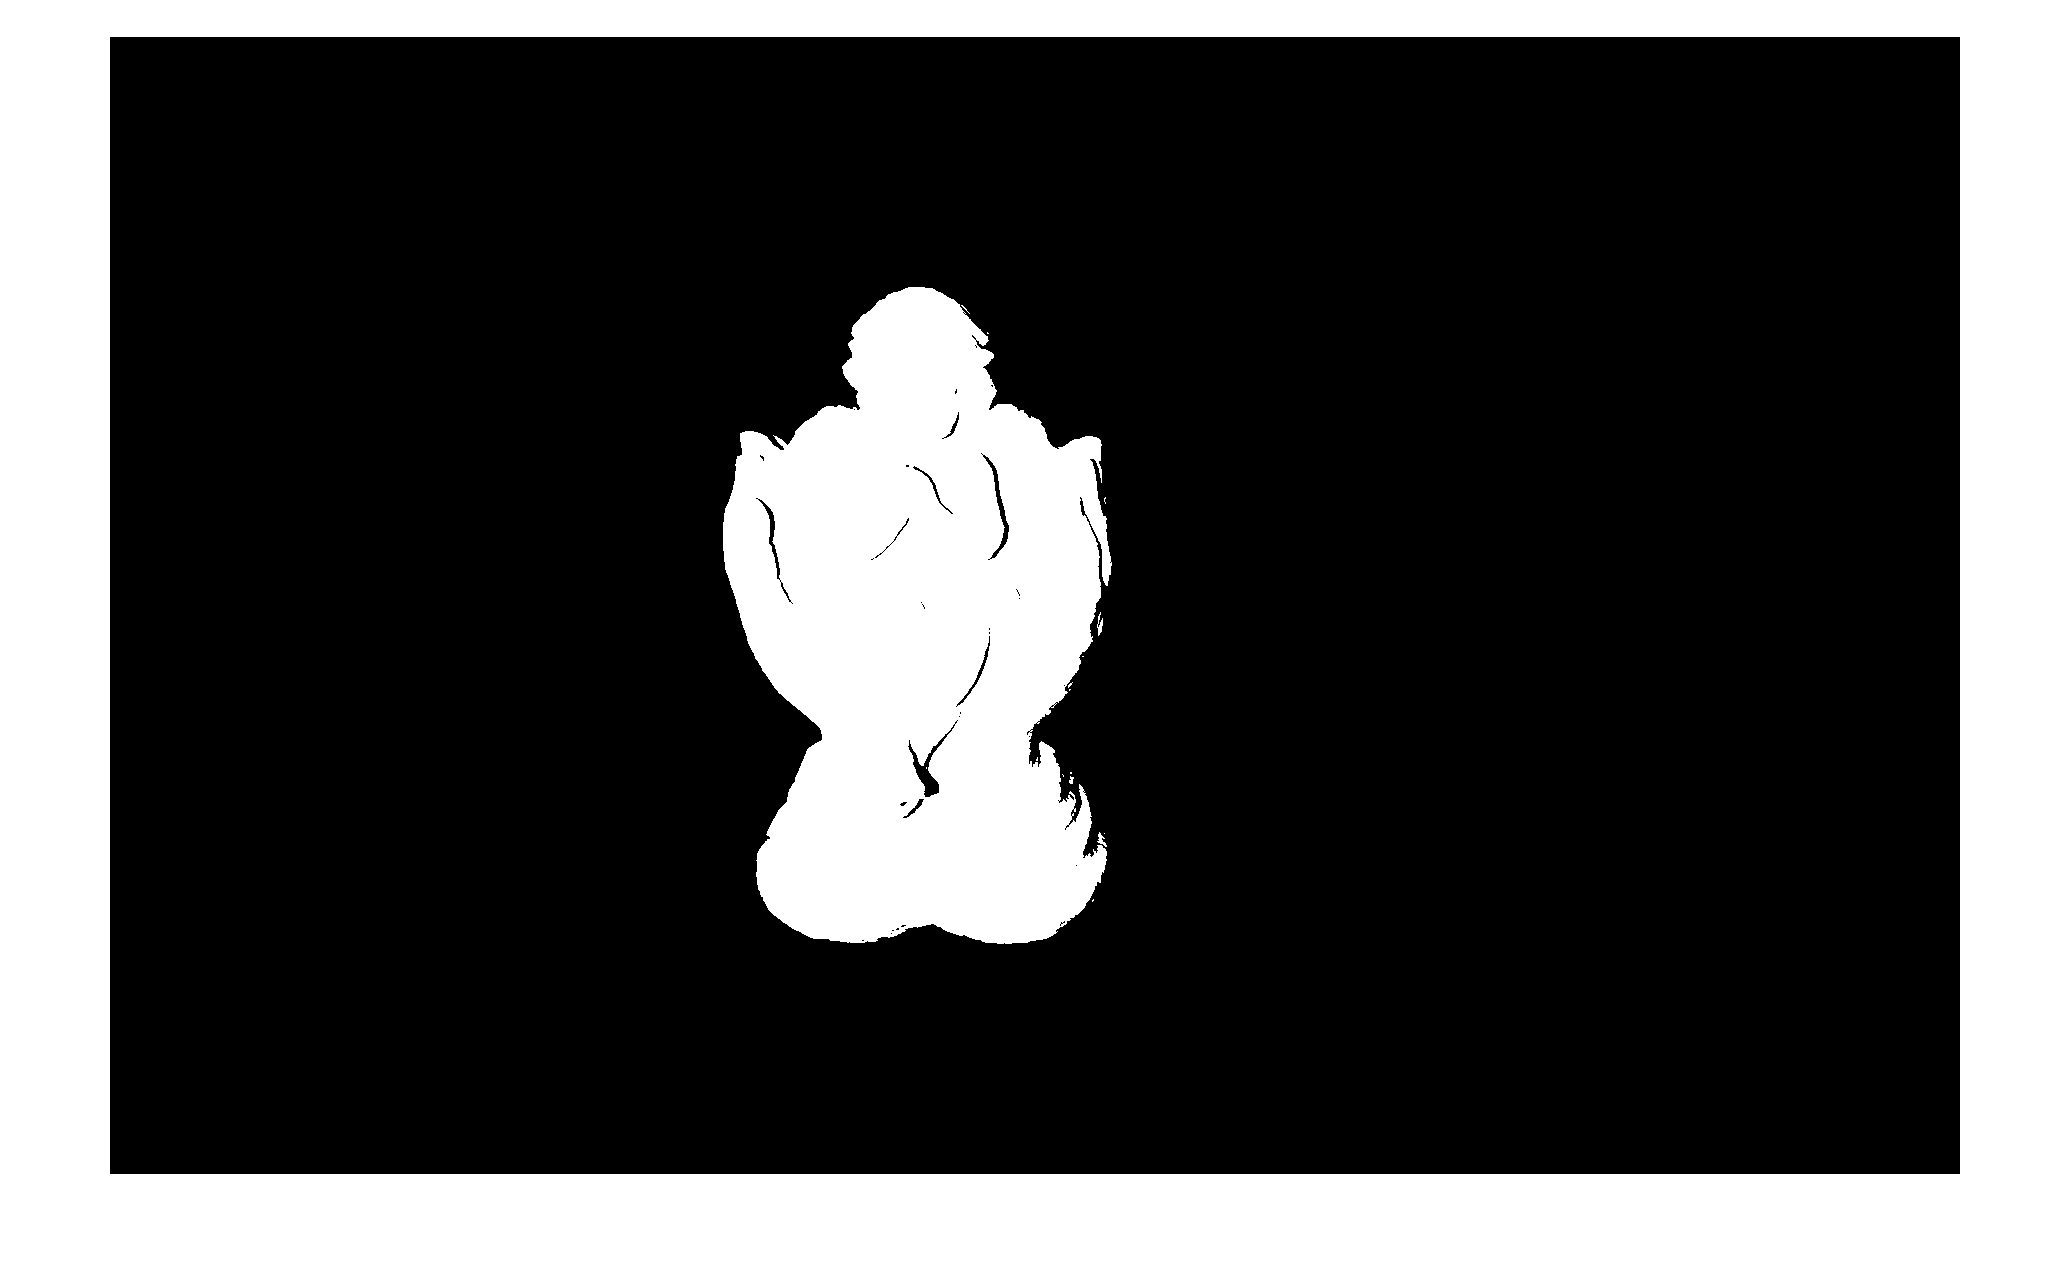

phase2 = decodePhase(prim2, sec2);
phase2 = phase2.*mask2;
figure;
imshow(phase2);

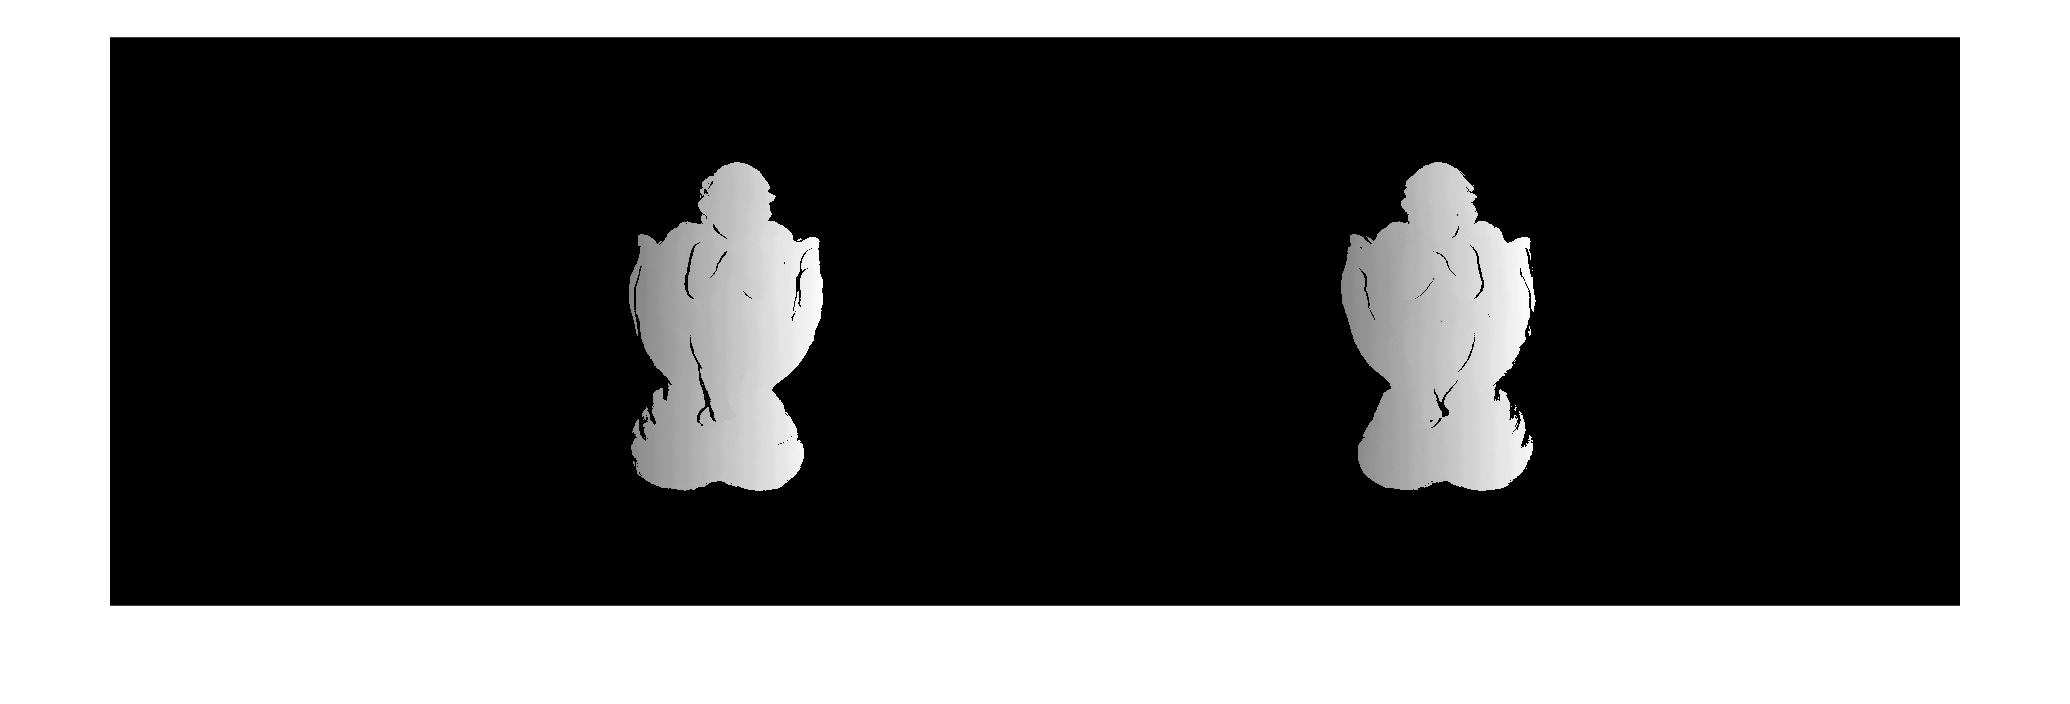

figure;
imshowpair(phase1, phase2, 'montage');

## Question 5

Phase Matching

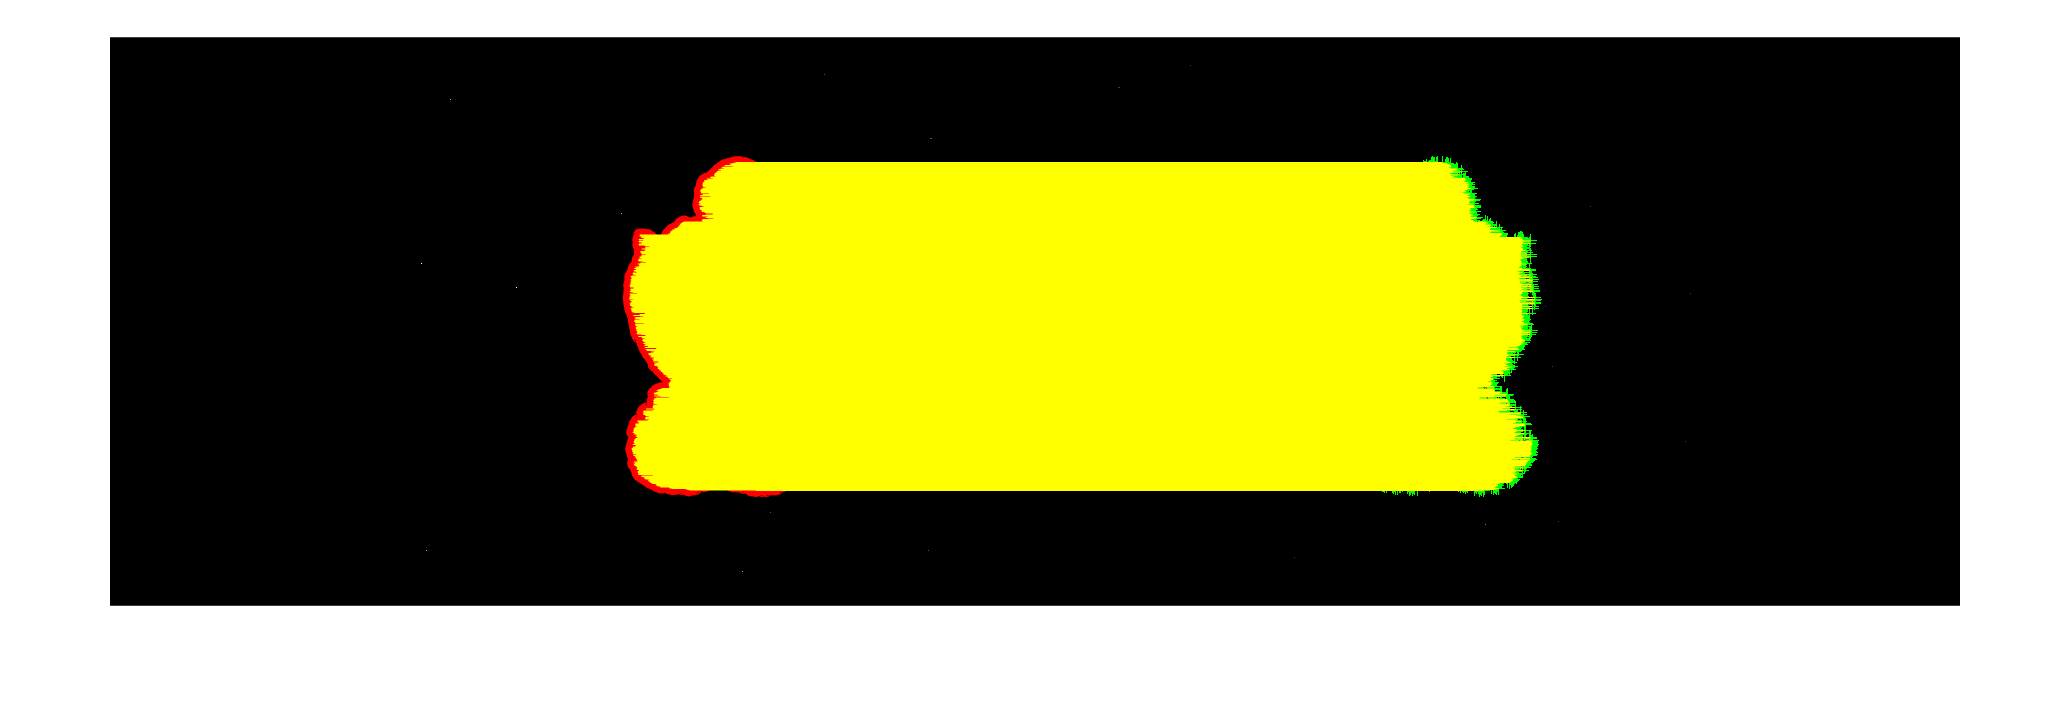

[q1, q2] = registerContinuous(phase1, phase2, mask1, mask2);
showMatchedFeatures(im0_1, im1_1, q1, q2, 'montage');

## Question 6

Triangulation

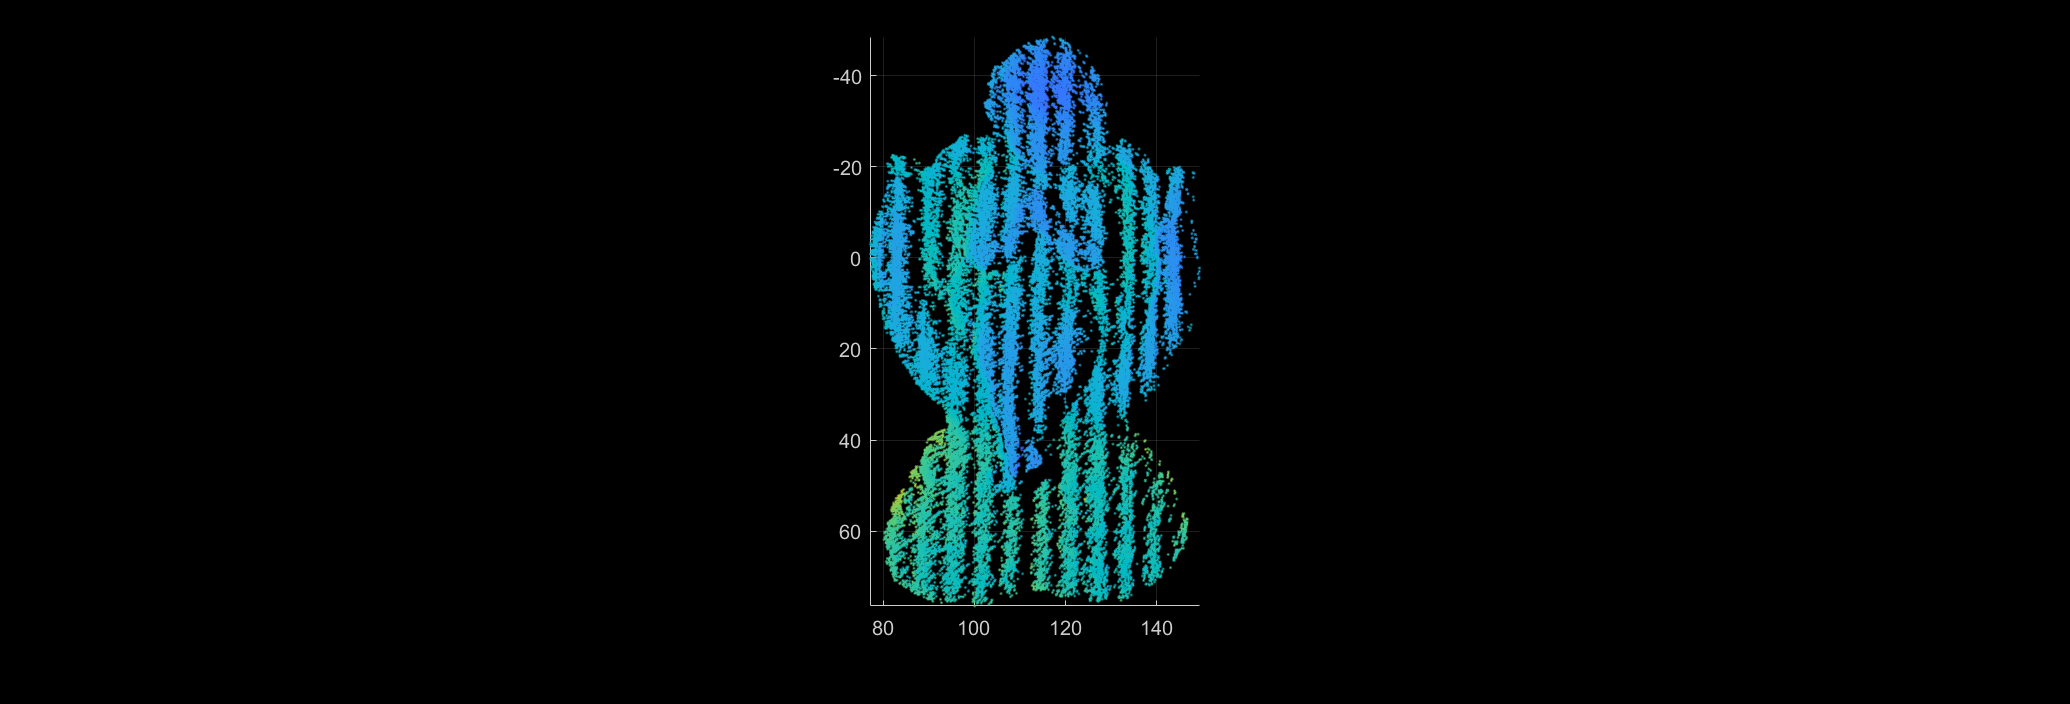

% Get the original camera matrices
P1 = cameraMatrix(stereo_params.CameraParameters1, eye(3), zeros(1, 3))';
P2 = cameraMatrix(stereo_params.CameraParameters2, stereo_params.RotationOfCamera2, stereo_params.TranslationOfCamera2)';

% In case of rectification:
% Do not use this if you loaded the pre-rectified images during
% your camera calibration. This method uses, in fact,
% undocumented features. I don't know when it will stop working.
H1 = stereo_params.toStruct().RectificationParams.H1';
H2 = stereo_params.toStruct().RectificationParams.H2';
origin = [0 0];
origin(1) = stereo_params.toStruct().RectificationParams.XBounds(1) - 1;
origin(2) = stereo_params.toStruct().RectificationParams.YBounds(1) - 1;
% Transform the real camera porjections into the rectified cameras:
% to: translation of origin:
to = [1 0 -origin(1); 0 1 -origin(2); 0 0 1];
P1 = to * H1 * P1;
P2 = to * H2 * P2;

Q = triangulate(q1, q2, P1', P2'); % Matlab uses a transposed version of the projection matrix
ptCloud = pointCloud(Q);
pcshow(ptCloud); view([0 -90])

## Rectification

take image0 for example

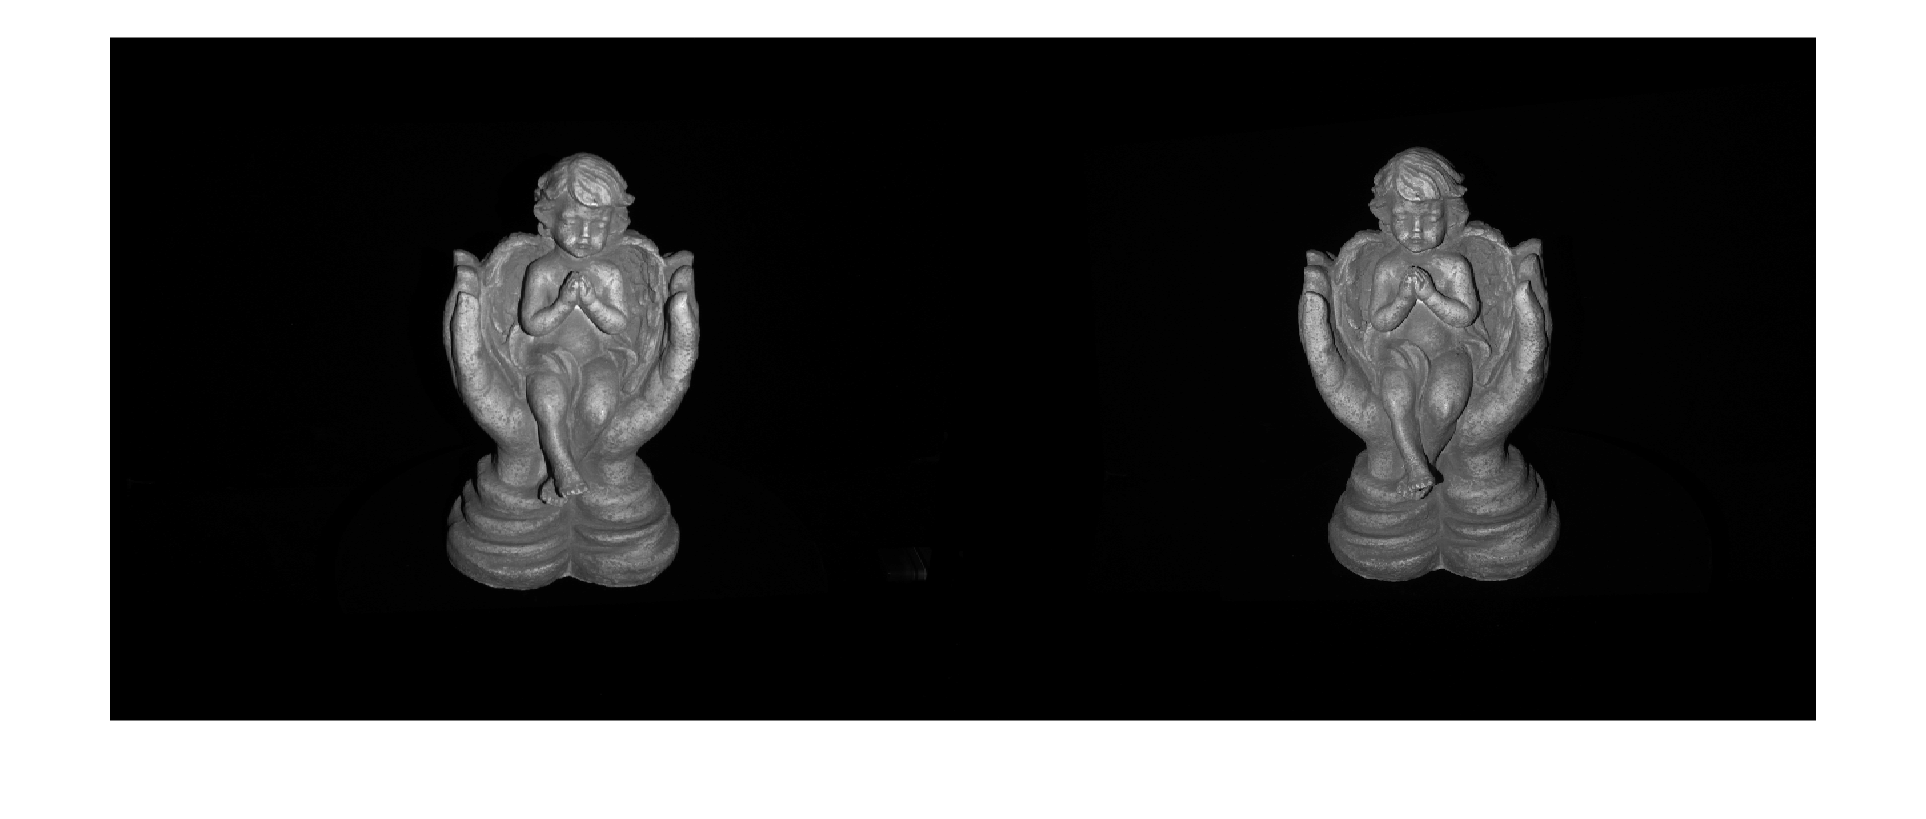

I1 = imread('angel/frames0_0.png');
I2 = imread('angel/frames1_0.png');
I1 = rgb2gray(I1);
I2 = rgb2gray(I2);
figure;
imshowpair(I1, I2, 'montage');

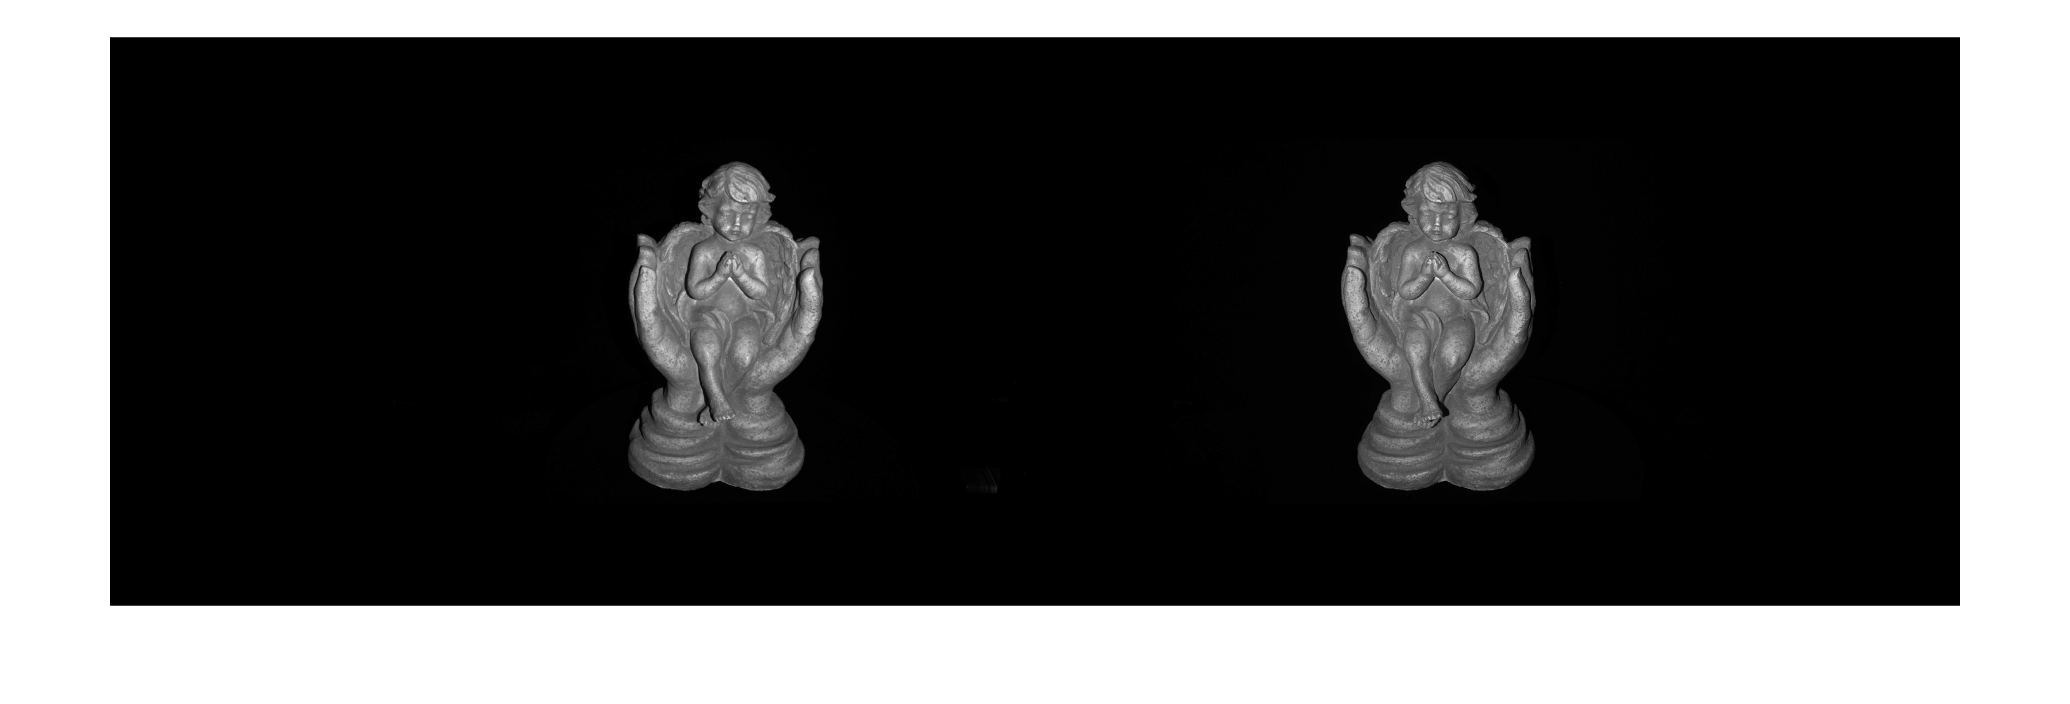

[J1,J2] = rectifyStereoImages(I1,I2,stereo_params, 'OutputView',"full");
figure;
imshowpair(J1,J2,'montage');

## What about the ply

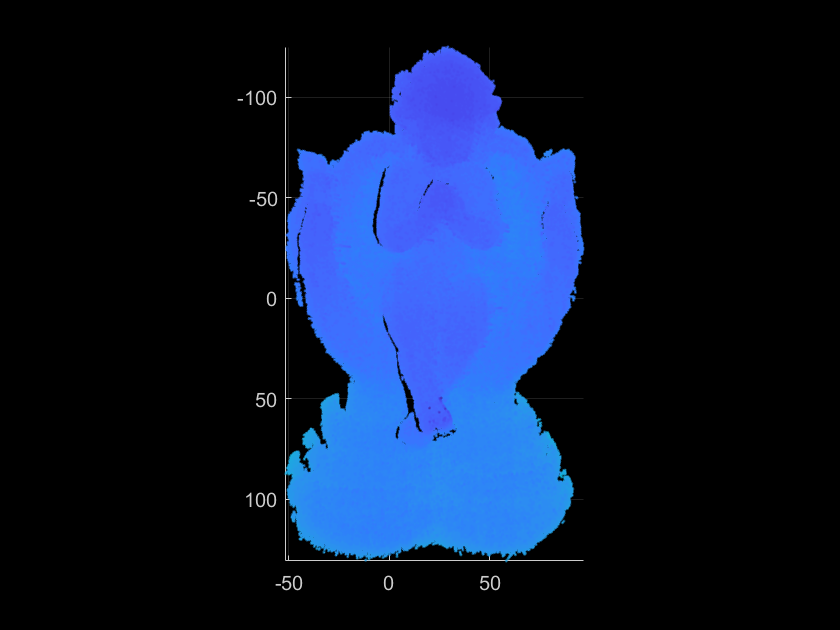

pc = pcread('angel.ply');
pcshow(pc);view([0 -90]);

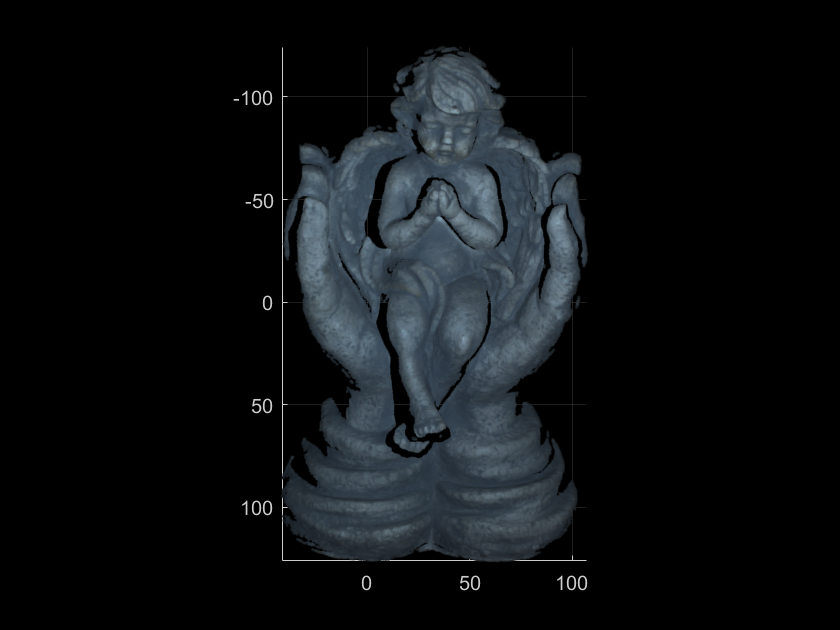

pc = pcread('angel_real.ply');
pcshow(pc);view([0 -90]);